# Group Assignment

SID: 480564906, XXX, XXX

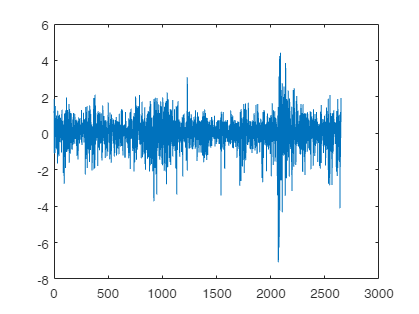

tbl = readtable("AORD_2012_2022.xlsx");
% Centering the returns
returns = tbl.Return - mean(tbl.Return);
y = returns;

plot(y)

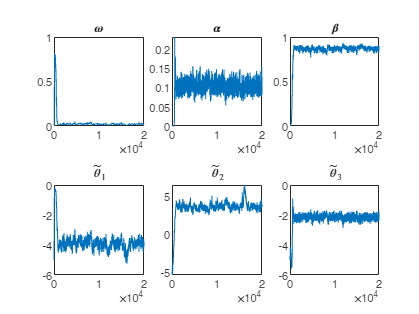

means =     0.0207    0.1028    0.8698


stds =     0.0063    0.0141    0.0202


qs =     0.0098    0.0344    0.0771    0.1322    0.8247    0.9054



rng(3830)

[means,stds,qs]=perform_RWMH(20000,y,eye(3)*0.01,1,0,1,1)

function joint_prior = get_joint(phi)
    alpha = phi(2);
    beta = phi(3);
    gamma_part = gamma(11.5)/(gamma(10)*gamma(1.5));
    alpha_part = (alpha^0.5)*((1-alpha)^9);
    beta_part = (beta^9)*((1-beta)^0.5);
    joint_prior = (gamma_part^2)*alpha_part*beta_part;
end
    

function sigma2 = get_sigma2(y,phi)
    omega=phi(1);
    alpha=phi(2);
    beta=phi(3);

    T = length(y);
    sigma2 = zeros(T,1);
    
    for t=1:T
        if t==1
            sigma2(t) = var(y); 
        else    
            sigma2(t) = omega+(alpha*(y(t-1)^2))+beta*(sigma2(t-1));
        end   
    end
    
end

function llh = group_log_likelihood(y,sigma2)
    summation = sum(log(2*pi)+log(sigma2)+((y.^2)./sigma2));
    llh = -0.5*summation;
end


function phi = get_phi(theta)
theta1 = theta(1);
theta2 = theta(2);
theta3 = theta(3);
omega = exp(theta1);
alpha = (exp(theta2)*exp(theta3))/(1+exp(theta2)+exp(theta3)+exp(theta2)*exp(theta3));
beta = exp(theta2)/(1+exp(theta2)+exp(theta3)+exp(theta2)*exp(theta3));

phi = [omega,alpha,beta];
end


function [mean_phis, std_phis, Q] = perform_RWMH(Niter,y,RWMH_Sigma,plots,adaptive,means_stds, quantiles)
dim = 3; % the dimension of phis and thetas

markov_chain_theta = zeros(Niter,dim); 
markov_chain_phi = zeros(Niter,dim); 

theta0 = -5 + (-5+5)*rand(1,dim); % starting value for our omega,alpha,betas
phi0 = get_phi(theta0);
markov_chain_theta(1,:) = theta0;
markov_chain_phi(1,:) = phi0;

current_sigma2 = get_sigma2(y,markov_chain_phi(1,:));

i = 1;
while i<Niter
    %if I want to use the adaptive RWMH_Sigma
    if adaptive==1 && i<=1000
        RWMH_Sigma=((0.1^2)/dim)*eye(dim); 
    elseif adaptive==1 && i>1000
        RWMH_Sigma = 0.05*((0.1^2)/dim)*eye(dim) +(1-0.05)*((2.38^2)/dim)*cov(markov_chain_phi(i-1000:i,:));% update RWMH_Sigma based on the last 1000 iterations
    else
        ; %just keep RWMH_Sigma as provided, not adaptive.
    end
        
    epsilon = mvnrnd(zeros(3,1),RWMH_Sigma);
    proposal_theta= markov_chain_theta(i,:)+epsilon;
    proposal = get_phi(proposal_theta);

    proposal_sigma2 = get_sigma2(y,proposal);

    %rejection/acceptance
    aux_proposal =group_log_likelihood(y,proposal_sigma2)+log(get_joint(proposal));
    aux_current = group_log_likelihood(y,current_sigma2)+log(get_joint(markov_chain_phi(i,:)));
    auxiliary =aux_proposal-aux_current;
    
    rejection_threshold = min(exp(auxiliary),1);
    u = rand;
    if u<rejection_threshold %&& proposal(1)>0 && proposal(2)>0 && proposal(3)>0 && (proposal(2)+proposal(3))<1
        %naive checking satisfactory proposal
        markov_chain_phi(i+1,:) = proposal;
        markov_chain_theta(i+1,:) = proposal_theta;
        current_sigma2 = proposal_sigma2;
    else
        markov_chain_phi(i+1,:) = markov_chain_phi(i,:);
        markov_chain_theta(i+1,:) = markov_chain_theta(i,:);
    end
    i = i+1;
end
%if i want to make traceplots
if plots==1
    subplot(2,3,1)
    plot(markov_chain_phi(:,1))
    title('\omega')

    subplot(2,3,2)
    plot(markov_chain_phi(:,2))
    title('\alpha')

    subplot(2,3,3)
    plot(markov_chain_phi(:,3))
    title('\beta')

    subplot(2,3,4)
    plot(markov_chain_theta(:,1))
    title('$\tilde{\theta}_1$', 'interpreter', 'latex')

    subplot(2,3,5)
    plot(markov_chain_theta(:,2))
    title('$\tilde{\theta}_2$', 'interpreter', 'latex')

    subplot(2,3,6)
    plot(markov_chain_theta(:,3))
    title('$\tilde{\theta}_3$', 'interpreter', 'latex')
end

%toss burn-in period (rows 0 to 1000)
mean_phis = transpose([mean(markov_chain_theta(5000:Niter,1))
    mean(markov_chain_theta(5000:Niter,2))
    mean(markov_chain_theta(5000:Niter,3))]);

mean_phis = transpose([mean(markov_chain_phi(5000:Niter,1))
    mean(markov_chain_phi(5000:Niter,2))
    mean(markov_chain_phi(5000:Niter,3))]);
%if i also want to return the standard deviations for each ß
if means_stds==1
    std_phis = transpose([std(markov_chain_phi(5000:Niter,1))
    std(markov_chain_phi(5000:Niter,2))
    std(markov_chain_phi(5000:Niter,3))]);
end

if quantiles == 1
    Q = [quantile(markov_chain_phi(5000:Niter,1),[0.025 0.975]) ...
        quantile(markov_chain_phi(5000:Niter,2),[0.025 0.975]) ...
        quantile(markov_chain_phi(5000:Niter,3),[0.025 0.975])];
end

end
